ciqData = readtable('Data.csv');
ciqData.IQ_PAYOUT = ciqData.IQ_DIV_SHARE - ciqData.CF_DECR_CAP_STOCK - ciqData.CF_INCR_CAP_STOCK;
ciqData.BBG_BB = - ciqData.CF_DECR_CAP_STOCK - ciqData.CF_INCR_CAP_STOCK;

INCOME_STATEMENT = 6 : 14;
BALANCE_SHEET = 15 : 22;
CASH_FLOW = 23 : 25;
RATIOS = 26 : 31;

Following block was done June 29-30: 

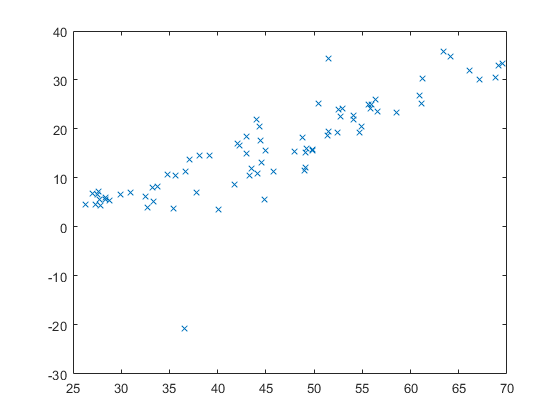

y0 = ciqData.IQ_PAYOUT; % IQ_DIV_SHARE, DVD_SH_12M, IQ_BB, IQ_PAYOUT
X0 = ciqData.IQ_EBITDA; % IQ_EBIT, IQ_BASIC_EPS_EXCL, 
y = y0(2:end,1); 
X = [y0(1:end-1,1),X0(2:end,1)]; 
o = regstats(y,X,'linear',{'tstat','r','yhat','dwstat','rsquare'}); 
rho = autocorr(o.r,'NumLags',2); 
% Output Arguments:
%   acf - Sample ACF. Vector of length NumLags+1 of values computed at lags
%       0,1,2,...,NumLags. For all y, acf(1) = 1 at lag 0.
%   lags - Vector of lag numbers of length NumLags+1 used to compute acf.
%   bounds - Two-element vector of approximate upper and lower confidence
%       bounds, assuming that y is an MA(NumMA) process.
%   h - Vector of handles to plotted graphics objects. AUTOCORR plots the
%       ACF when the number of output arguments is 0 or 4.

% spec 2
y = y0(3:end,1); 
X = [y0(2:end-1,1),y0(1:end-2,1),X0(3:end,1)]; 
o = regstats(y,X,'linear',{'tstat','r','yhat','dwstat','rsquare'}); 
figure(1); plot(X(:,3),y,'x')

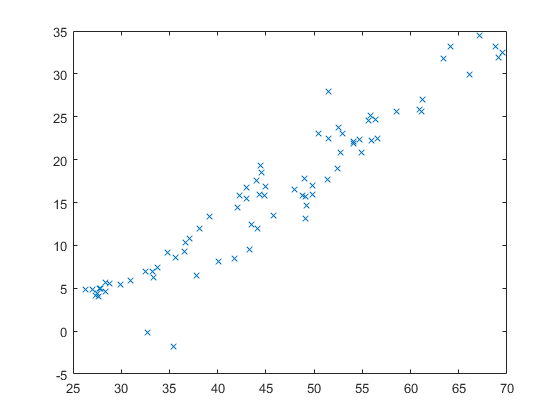

figure(2); plot(X(:,3),o.yhat,'x')

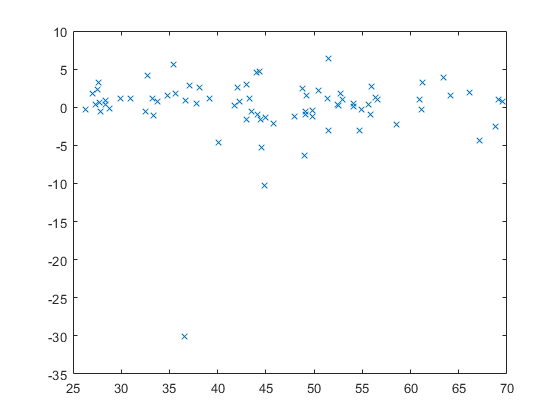

figure(3); plot(X(:,3),o.r,'x')


% spec 3
y = y0(3:end,1); 
X = [y0(2:end-1,1),(y0(2:end-1,1)-y0(1:end-2,1)),X0(3:end,1),(X0(3:end,1)-X0(2:end-1,1))]; 
o = regstats(y,X,'linear',{'tstat','r','yhat','dwstat','rsquare'}); 
figure(1); plot(X(:,3),y,'x')

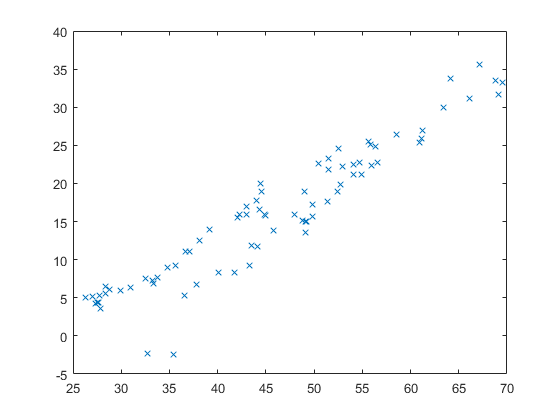

figure(2); plot(X(:,3),o.yhat,'x')

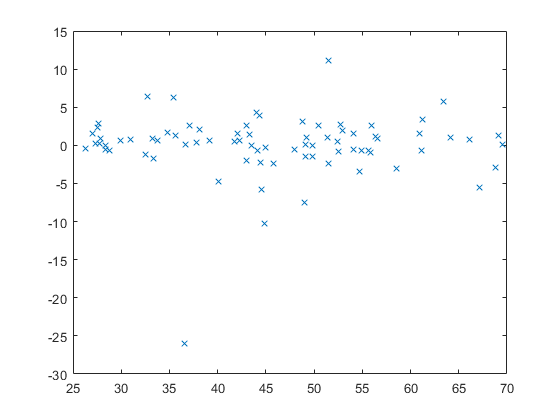

figure(3); plot(X(:,3),o.r,'x')

After writing / running that block I wrote Eileen the following:

"I think I understand a few things better now:  

- We should estimate forward buy-backs and forward dividends separately.

- The dividend equation should always have DIV(t-1) on the RHS – that will get rid of your autocorrelated errors (your DWs below are around 1; I got them to be 2 by adding a lagged independent variable term).

- Given 2, we should do a 2-stage regression for dividends. First stage: run DIV(t) = alpha + beta*DIV(t-1) + u(t)

Second stage: create a new variable, yy(t) = alpha + u(t), i.e., a residual w/ a non-zero mean.  On THIS independent variable we use our orthogonalized regressors: 

yy(t) = alpha2 + beta2*EBITDA(t) + beta3*(CFPS(t) – rho1*EBITDA(t)) + … + u2(t)

Note, in your example below rho = 0.7.  Also note, we need to check the stability of rho.  If it is 0.3 for the first half of the sample but 1.1 the second half, and has a low t-stat, this means our orthogonalization probably won’t hold up on a forward basis.

 I bet you find that your R^2 on this 2-stage regression is in the low 90s.  You compute R^2 for a 2-stage regression with 1 – VAR(u2(t))/VAR(DIV(t)).

Final note: we can use lagged values of variables without good forward estimates.  We can only use contemporary terms with EBIT, EBITDA, EPS, sales, etc. 

This next block done 3 July, responding to Eileen's email of the same date; 

% Eileen's first pass model: there is a unit root in dividends
y0 = ciqData.IQ_DIV_SHARE; % IQ_DIV_SHARE, DVD_SH_12M, IQ_BB, IQ_PAYOUT
X0 = [ciqData.IQ_EBIT, ciqData.IQ_DILUT_EPS_EXCL, ciqData.IQ_RETURN_EQUITY, ciqData.IQ_RETURN_CAPITAL]; % IQ_EBIT, IQ_BASIC_EPS_EXCL, 
y = y0(2:end,1); 
X = y0(1:end-1,1); 
o = regstats(y,X,'linear',{'tstat','r','yhat','dwstat','rsquare'}); 
yy = o.tstat.beta(1)+o.r;

Note, the unit root poses a significant econometric problem (the variance of the level variables become explosive).  This becomes an issue of how big the autocorrelation coefficient is on the variable itself.  Consider the following specification: 


$$y_t =\alpha +\rho y_{t-1} +\beta_1 x_{1,t} +\beta_2 x_{2,t} +\cdots +\beta_N x_{K,t-k} +\varepsilon_t$$


If $\rho$is well below 1, say 0.9, then the variance of $y_t$ is not explosive, and including $y_t$ in levels is still sensible.  But if $\rho$is near 1 variance of $y_t$ becomes explosive and it throws off all of our inference statistics.  Of course if $\rho =1$then we have a really simple solution analytically: simply take the difference of  $y_t$, since we know it contains a random walk, and off of its interesting dynamics resid in its residuals: 


$$y_t =\alpha +\rho y_{t-1} +\beta_1 x_{1,t} +\beta_2 x_{2,t} +\cdots +\beta_N x_{K,t-k} +\varepsilon_t$$



$$y_t =\alpha +1y_{t-1} +\beta_1 x_{1,t} +\beta_2 x_{2,t} +\cdots +\beta_N x_{K,t-k} +\varepsilon_t$$


$y_t -1y_{t-1} =\alpha +\beta_1 x_{1,t} +\beta_2 x_{2,t} +\cdots +\beta_N x_{K,t-k} +\varepsilon_t$ or 


$$\left(y_t -y_{t-1} \right)=\alpha +\beta_1 x_{1,t} +\beta_2 x_{2,t} +\cdots +\beta_N x_{K,t-k} +\varepsilon_t$$


See [https://www.sas.upenn.edu/~fdiebold/papers/paper27/dk3.pdf](https://www.sas.upenn.edu/~fdiebold/papers/paper27/dk3.pdf) or [http://www.ru.ac.bd/stat/wp-content/uploads/sites/25/2019/03/504_02_Hamilton_Time-Series-Analysis.pdf.](http://www.ru.ac.bd/stat/wp-content/uploads/sites/25/2019/03/504_02_Hamilton_Time-Series-Analysis.pdf.)  On the Hamilton book go to the chapter on unit roots.

Note that given the coefficient of 1 for rho, the lagged value y(t-1) explains *a lot* of the variation in y(t).  Consequently when we move into differenced space ( *y(t) - y(t-1)* ) our R-squared statistics on the remaining variables fall a lot.  This is OK.  Our R-squared on the levels of *y(t)* will end up being very high.

One last thing we may want to do is normalize our levels: we can divide all variables by their prior values, i.e., express them in percent.  This will keep magnitudes in an easily interpretable range.


% New model: first stage of the prior model shows Div(t) = alpha+1.02*Div(t-1) + u(t): a unit root.
% So we will model the perc change in div: d(DIV(t))/DIV(t-1) = alpha + beta1*etc.
y = (y0(3:end,1)-y0(2:end-1,1))./y0(2:end-1,1); % perc chg in DIV
X = (X0(3:end,1) - X0(2:end-1,1))./X0(2:end-1,1); % perc chg in EBIT
X(:,2) = (X0(2:end-1,1) - X0(1:end-2,1))./X0(1:end-2,1); % lagged perc chg in EBIT
o1 = regstats(y,X,'linear',{'tstat','r','yhat','dwstat','rsquare'}); 

y = (y0(4:end,1)-y0(3:end-1,1))./y0(3:end-1,1); % perc chg in DIV
X = (X0(3:end-1,1) - X0(2:end-2,1))./X0(2:end-2,1); % lagged perc chg in EBIT
X(:,2) = (X0(2:end-2,1) - X0(1:end-3,1))./X0(1:end-3,1); % 2 qtr lagged perc chng in EBIT
o2 = regstats(y,X,'linear',{'tstat','r','yhat','dwstat','rsquare'}); 

y = (y0(5:end,1)-y0(4:end-1,1))./y0(4:end-1,1); % perc chg in DIV
X = (X0(4:end-1,1) - X0(3:end-2,1))./X0(3:end-2,1); % lagged perc chg in EBIT
X(:,2) = (X0(3:end-2,1) - X0(2:end-3,1))./X0(2:end-3,1); % 2 qtr lagged perc chng in EBITplot(X0(:,1),[y0,yHat])
X(:,3) = (X0(2:end-3,1) - X0(1:end-4,1))./X0(1:end-4,1); % 3 qtr lagged perc chng in EBIT
o3 = regstats(y,X,'linear',{'tstat','r','yhat','dwstat','rsquare'}); 


So the final spec is: 


$$\begin{array}{l}
y_t =\;\;\frac{\left({D\mathrm{iv}}_t -{D\mathrm{iv}}_{t-1} \right)}{{D\mathrm{iv}}_{t-1} }\\
x_{1,t} =\frac{\left({\mathrm{EBIT}}_t -{\mathrm{EBIT}}_{t-1} \right)}{{\mathrm{EBIT}}_{t-1} }
\end{array}$$



$$y_t =\alpha +\beta_1 x_{1,t} +\beta_2 x_{1,t-1} +\beta_3 x_{1,t-2} +\varepsilon_t$$



$$\begin{array}{l}
\alpha =0\ldotp 0127\\
\beta_1 =0\ldotp 1428\\
\beta_2 =0\ldotp 343\\
\beta_3 =0\ldotp 1407\\
R^2 =0\ldotp 2307
\end{array}$$


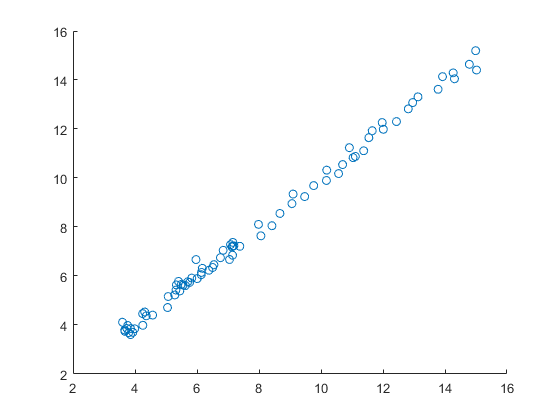

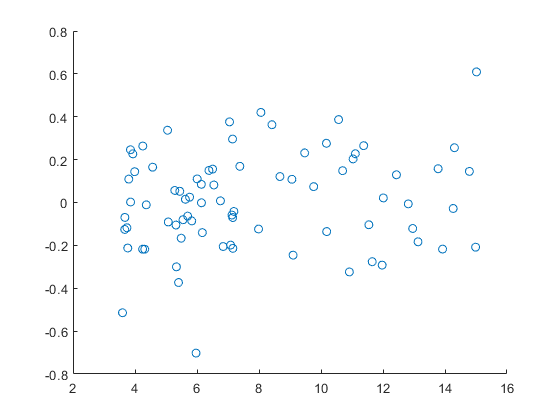

% FINAL SPEC:
% Run regression on percent change space:
y0 = ciqData.IQ_DIV_SHARE; % IQ_DIV_SHARE, DVD_SH_12M, IQ_BB, IQ_PAYOUT
X0 = [ciqData.IQ_EBIT, ciqData.IQ_DILUT_EPS_EXCL, ciqData.IQ_RETURN_EQUITY, ciqData.IQ_RETURN_CAPITAL]; % IQ_EBIT, IQ_BASIC_EPS_EXCL, 
y = (y0(4:end,1)-y0(3:end-1,1))./y0(3:end-1,1); % perc chg in DIV
X = (X0(4:end,1) - X0(3:end-1,1))./X0(3:end-1,1); % perc chg in EBIT
X(:,2) = (X0(3:end-1,1) - X0(2:end-2,1))./X0(2:end-2,1); % lagged perc chng in EBIT
X(:,3) = (X0(2:end-2,1) - X0(1:end-3,1))./X0(1:end-3,1); % 2 qtr lagged perc chng in EBIT
o4 = regstats(y,X,'linear',{'tstat','r','yhat','dwstat','rsquare'}); 

% transform percentage forecast to a forecast in levels:
yHat = nan(size(y0));
resids = nan(size(y0));
alpha = o4.tstat.beta(1)*y0(3:end-1,1); % alpha becomes a vector in time as we re-scale from prcnt units to levels 
beta1 = o4.tstat.beta(2);
beta2 = o4.tstat.beta(3);
beta3 = o4.tstat.beta(4);
yHat(4:end,:) = y0(3:end-1) + alpha + (beta1*X(:,1)+beta2*X(:,2)+beta3*X(:,3)).*y0(3:end-1,1);
resids(4:end,1) = o4.r.*y0(3:end-1,1);
rSqrd = 1-var(resids(4:end,1))/var(y0(4:end,1));

figure(1); scatter(y0,yHat)
figure(2); scatter(y0,resids)


On 12 July 2020: considering seasonality


$$y_t =\alpha +\alpha_{1,q} +\beta_1 x_{1,t} +\beta_2 x_{1,t-1} +\beta_3 x_{1,t-2} +\varepsilon_t$$



$$\begin{array}{l}
\alpha =0\ldotp 0127\\
\alpha_{1,1} =-0\ldotp 0119\\
\alpha_{1,2} =0\ldotp 0058\\
\alpha_{1,3} =0\ldotp 0112\\
\alpha_{1,4} =0\ldotp 0\\
\beta_1 =0\ldotp 1206\\
\beta_2 =0\ldotp 0939\\
\beta_3 =0\ldotp 2220\\
R^2 =0\ldotp 2646
\end{array}$$


The t-stats get uniformly worse, so the large increase in params (3), marginal improvement in r-squared and degredation in stat sig, suggests we do not implement... 

% Run regression on percent change space:
y0 = ciqData.IQ_DIV_SHARE; % IQ_DIV_SHARE, DVD_SH_12M, IQ_BB, IQ_PAYOUT
X0 = [ciqData.IQ_EBIT, ciqData.IQ_DILUT_EPS_EXCL, ciqData.IQ_RETURN_EQUITY, ciqData.IQ_RETURN_CAPITAL]; % IQ_EBIT, IQ_BASIC_EPS_EXCL, 
T = size(y0,1);
seasDum = zeros(T,4);
seasDum(:,1) = month(ciqData.DATE)==3;
seasDum(:,2) = month(ciqData.DATE)==6;
seasDum(:,3) = month(ciqData.DATE)==9;
%seasDum(:,4) = month(ciqData.DATE)==12;

y = (y0(4:end,1)-y0(3:end-1,1))./y0(3:end-1,1); % perc chg in DIV
X = (X0(4:end,1) - X0(3:end-1,1))./X0(3:end-1,1); % perc chg in EBIT
X(:,2) = (X0(3:end-1,1) - X0(2:end-2,1))./X0(2:end-2,1); % lagged perc chng in EBIT
X(:,3) = (X0(2:end-2,1) - X0(1:end-3,1))./X0(1:end-3,1); % 2 qtr lagged perc chng in EBIT
X = [seasDum(4:end,1:3),X];
o5 = regstats(y,X,'linear',{'tstat','r','yhat','dwstat','rsquare'}); 
